# Lesson II.8: Orthogonal Projection, Least Squares Solutions and Regression  

**Orthogonal projection.  **Suppose that $V\subset{\mathbb R}^m$ is a subspace and ${\bf x}\in{\mathbb R}^m$.   The orthogonal projection of ${\bf x}$ into $V$ is the point ${\bf p}$ in $V$ closest to ${\bf x}$.

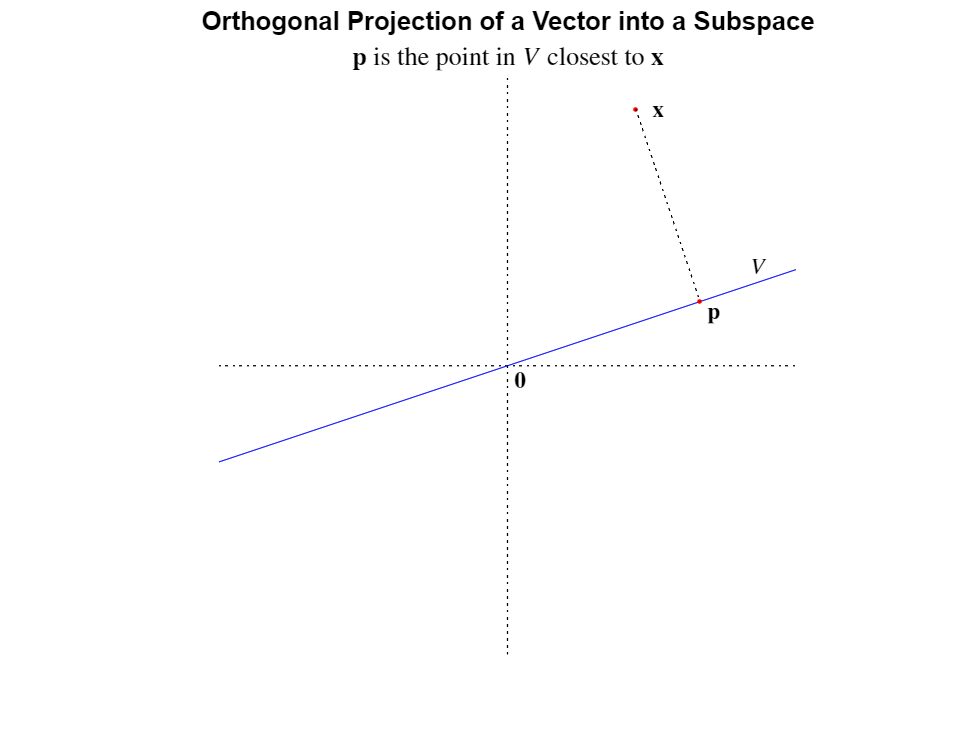

figII8a()

The key geometric relationship is that the vector ${\bf x}-{\bf p}$ is orthogonal to the vector space $V$ (i.e., ${\bf x}-{\bf p}\in V^\perp$):

        (II.8.1)        ${\bf v}\cdot({\bf x}-{\bf p})=0\qquad\text{for all}~{\bf v}\in V$.

This relationship (derived in Appendix II.8A) is the reason the process of obtaining ${\bf p}$ from ${\bf x}$ is known as ***orthogonal projection***.  

Consider the problem of computing an orthogonal projection when $V$ has a basis$\{{\bf a}_1,\dots,{\bf a}_k\}$.   We seek coefficients $\alpha_1,\dots,\alpha_2$ such that ${\bf p}=\alpha_1{\bf a}_1+\cdots+\alpha_k{\bf a}_k$.   It is helpful to rewrite this linear combination as a matrix-vector product:

        (II.8.2)        ${\bf p}=A {\bf \alpha}$        where         $A=\left[\matrix{{\bf a}_1&\cdots&{\bf a}_k}\right]$    and    ${\bf \alpha}=\left[\matrix{\alpha_1\cr\vdots\cr\alpha_k}\right]$.

We plan to plug this representation for ${\bf p}$ into (II.8.1) and to then solve for solve for ${\bf \alpha}$.   However, we need to address one issue first.   In principle, equation (II.8.1) defines an infinite collection of linear equations for ${\bf p}$, one for every ${\bf v}$ in $V$.  Happily, it suffices to solve the finite system obtained by restricting ${\bf v}$ to a basis of $V$.   That is, the solution set for (II.8.1) is the same as the solution set for 

        (II.8.3a)        ${\bf a}_\ell\cdot({\bf x}-{\bf p})=0\qquad\text{for}~\ell=1,\dots,k$. 

This system can be rewritten in matrix form as $A^T({\bf x}-{\bf p})={\bf 0}$.   After substituting (II.8.2) into the equation

        (II.8.3b)        $A^TA{\bf \alpha}={\bf b}$    where    ${\bf b}=A^T{\bf x}$.

Notice that the coefficient matrix of this linear system for the coefficient vector ${\bf \alpha}$ is the $k\times k$ Gram matrix of the $m\times k$ matrix $A$.   As shown in Appendix II.8B, the Gram matrix of a matrix having linearly independent columns is always invertible.   Hence, we find ${\bf\alpha}=(A^TA)^{-1}{\bf b}=(A^TA)^{-1}A^T{\bf x}$.   Substituting this into (II.8.2) gives

        (II.8.4)        ${\bf p}=A(A^TA)^{-1}A^T{{\bf x}$.

That is, the process of orthogonal projection of a vector ${\bf x}$ into a subspace $V$  with basis $\{{\bf a}_1,\dots,{\bf a}_k\}$ is accomplished by multiplying ${\bf x}$ by the $m\times m$ matrix

        (II.8.5)        $P~=~A(A^TA)^{-1}A^T$.                      (worth memorizing)

This matrix is a projection 

        (II.8.6a)        $P^2=A(A^TA)^{-1}A^T\,A(A^TA)^{-1}A^T=
A\bigg[(A^TA)^{-1}(A^TA)\bigg](A^TA)^{-1}A^T=A(A^TA)^{-1}A^T=P$

and is symmetric

        (II.8.6b)       $P^T~=~\big(A(A^TA)^{-1}A^T\big)^T=(A^T)^T(A^TA)^{-T}A^T=A (A^TA)^{-1} A^T=P$.

Algebraically, a projection matrix that is symmetric is called an ***orthogonal projection***.   The geometric basis for this terminology is evident from the earlier figure.

**Example II.8.1:**   Find the orthogonal projection matrix that projects into the plane spanned by ${\bf a}_1=\left[\matrix{1\cr0\cr2}\right]$ and ${\bf a}_2=\left[\matrix{0\cr3\cr2}\right]$.

  First form the matrix $A$ having the basis as column vectors:  $A=\left[\matrix{1 &0\cr0&3\cr2&2}\right]$.  Then compute the inverse of the Gram matrix:   $\big(A^TA\big)^{-1}=\left(\left[\matrix{1&0&2\cr0&3&2}\right]\left[\matrix{1&0\cr0&3\cr2&2}\right]\right)^{-1}=\left[\matrix{5 & 4\cr 4 &13}\right]^{-1}=\frac{1}{65-16}\left[\matrix{13&-4\cr-4&5}\right]=\left[\matrix{\frac{13}{49} & -\frac{4}{49}\cr-\frac{4}{49} & \frac{5}{49}}\right]$.   Premultiply by $A$ and postmultiply by $A^T$ to obtain $P=\left[\matrix{1&0\cr0&3\cr2&2}\right]
\left[\matrix{\frac{13}{49} & -\frac{4}{49}\cr-\frac{4}{49} & \frac{5}{49}}\right]
\left[\matrix{1&0&2\cr0&3&2}\right]=\frac{1}{49}
\left[\matrix{13&-12&18\cr-12&45&6\cr18&6&40}\right]$.

format rat
A=[1 0; 0 3; 2 2];
P=A*inv(A'*A)*A'

P =       13/49         -12/49          18/49    
     -12/49          45/49           6/49    
      18/49           6/49          40/49    


If the point ${\bf x}$ is already in the subspace $V$ then obviously the closest point in $V$ to ${\bf x}$ is itself, i.e.,

        (II.8.7)        $P{\bf x}={\bf x}$    for    ${\bf x}\in V$.

An immediate implication of (II.8.7) is that 

        (II.8.8)        $\text{col}(P)=\text{col}(A)=V$.

Moreover, since $P$ is symmetric ($P^T=P$), so the column space equals the row space.   

**Projection into the orthogonal complement.**   Consider the matrix $Q=I-P$.    It is easy to check that $Q$ is an orthogonal projection matrix:

        
$$Q^2=(I-P)^2=(I-P)(I-P)=I-P-P+P^2=I-P-P+P=I-P=Q$$


and

        $Q^T=(I-P)^T=I^T-P^T=I-P=Q$.

To where does $Q$ project?  

        
$${\bf x}\in V\quad\Leftrightarrow\quad
{\bf x}=P{\bf x}\Leftrightarrow\quad
I{\bf x}=P{\bf x}\quad\Leftrightarrow\quad
(I-P){\bf x}={\bf 0}\quad\Leftrightarrow\quad
Q{\bf x}={\bf 0}$$


That is, 

        (II.8.9a)        $V=\text{col}(P)=\text{nul}(Q).
$

Hence, taking the orthogonal complements of each subspace here:

        (II.8.9b)        $V^\perp=\text{col}(P)^\perp=\text{col}(Q)$.

Thus, $Q{\bf x}$ is the orthogonal projection of ${\bf x}$ into $V^\perp$.  

The matrices $Q$ and $P$ can be used to decompose a vector ${\bf x}$ into orthogonal components ${\bf p}=P{\bf x}\in V$ and ${\bf q}=Q{\bf x}\in V^\perp$.  

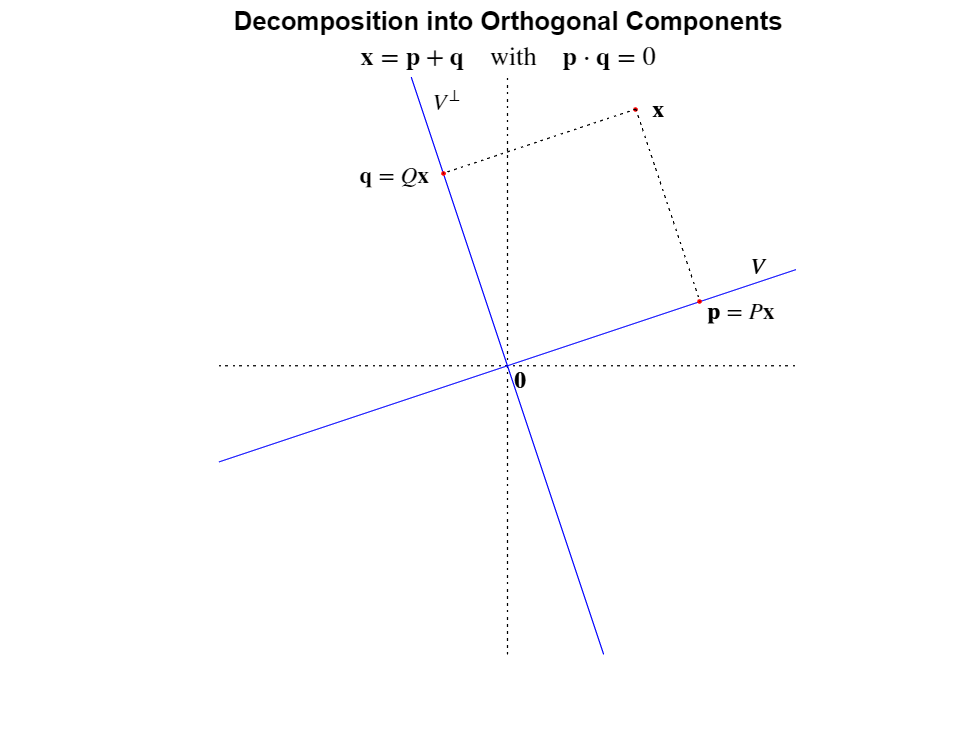

figII8b()

Two easily proved matrix identities 

        (II.8.10ab)        $P+Q=I$   and    $PQ=QP=O\qquad(\text{where}~O~\text{is the}~n\times n~\text{zero matrix})$

can be used to demonstrate algebraically the salient geometric features of the decomposition illustrated in the figure above:

        (II.8.11a)        ${\bf x}=I{\bf x}=(P+I-P){\bf x}=P{\bf x}+(I-P){\bf x}=P{\bf x}+Q{\bf x}={\bf p}+{\bf q}$

        (II.8.11b)        ${\bf p}\cdot{\bf q}=(P{\bf x})\cdot(Q{\bf x})=(P{\bf x})^T(Q{\bf x})={\bf x}^TP^TQ{\bf x}={\bf x}^TPQ{\bf x}={\bf x}^TO{\bf x}=0.$

**Simplifications for an orthonormal basis.   **In case the basis $\{{\bf a}_1,\dots,{\bf a}_k\}$for $V
$ is orthonormal (${\bf a}_\ell\cdot{\bf a}_\ell=1$and ${\bf a}_i\cdot{\bf a}_j=0 $ for $i\ne j$ ) the formula (II.8.4) for the projection matrix $P$ simplifies dramatically because the Gram matrix is the identity ($A^TA=I$):

        (11.9.12)        $P=AA^T$=${\bf a}_1{\bf a}_1^T+\cdots+{\bf a}_k{\bf a}_k^T={\bf a}_1\otimes{\bf a}_1+\cdots+{\bf a}_k\otimes{\bf a}_k$.

That is, $P$ is the Gram matrix of $A^T$ which can be written as the sum of the outer products of the columns of $A$ with themselves.

a1=[1/2;1/2;1/2;1/2];
a2=[1/2;-1/2;1/2;-1/2];
A=[a1 a2]

A =        1/2            1/2     
       1/2           -1/2     
       1/2            1/2     
       1/2           -1/2     


A'*A

ans =        1              0       
       0              1       


P=A*A'

P =        1/2            0              1/2            0       
       0              1/2            0              1/2     
       1/2            0              1/2            0       
       0              1/2            0              1/2     


A1=a1*a1'

A1 =        1/4            1/4            1/4            1/4     
       1/4            1/4            1/4            1/4     
       1/4            1/4            1/4            1/4     
       1/4            1/4            1/4            1/4     


A2=a2*a2'

A2 =        1/4           -1/4            1/4           -1/4     
      -1/4            1/4           -1/4            1/4     
       1/4           -1/4            1/4           -1/4     
      -1/4            1/4           -1/4            1/4     


A1+A2

ans =        1/2            0              1/2            0       
       0              1/2            0              1/2     
       1/2            0              1/2            0       
       0              1/2            0              1/2     


**Least squares solutions.   **A linear system $A{\bf x}={\bf b}$ has no solution if ${\bf b}\notin\text{col}(A)$.   In such situations, it is often useful to consider ***least-squares*** solutions where $A{\bf x}$ need not equal ${\bf b}$ but is made to be as close as possible to ${\bf b}$ (i.e., ${\bf x}$ minimizes $||A{\bf x}~-~{\bf b}||$).    That is, the least-squares solutions satisfy $A{\bf x}=\hat{\bf b}$ where $\hat {\bf b}$ is the orthogonal projection of ${\bf b}$ onto $\text{col}(A)$.   

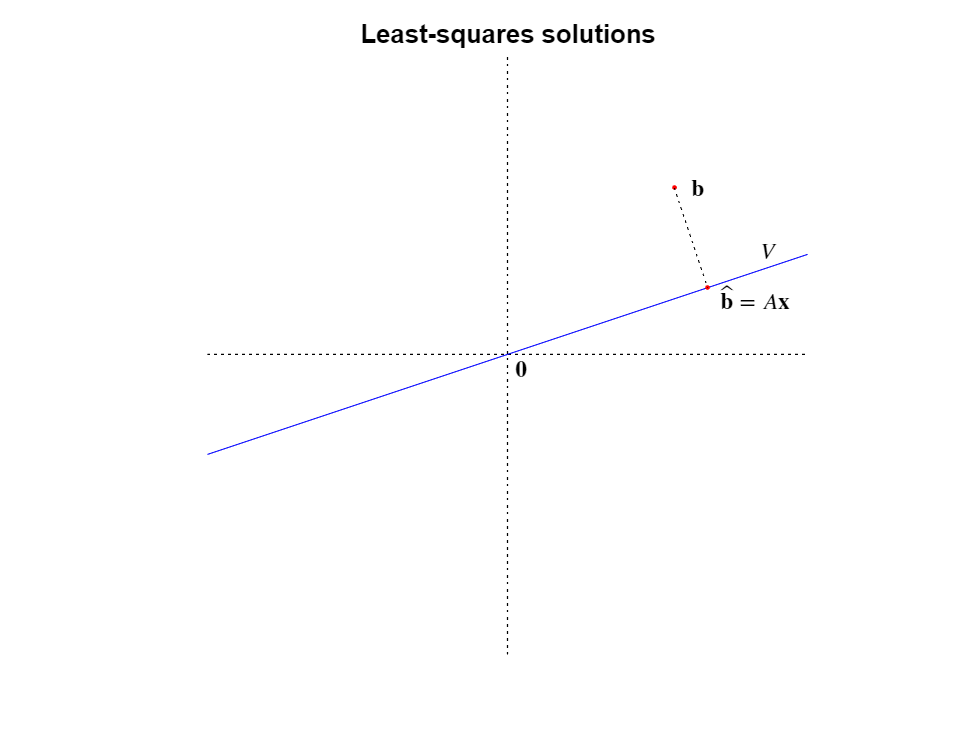

figII8c()

Since $\hat {\bf b}$ is characterized by the orthogonality of ${\bf b}-\hat {\bf b}$ to $\text{col}(A)$, $A^T({\bf b}-\hat{\bf b})={\bf 0}$.  Hence, $A^T({\bf b}-A{\bf x})={\bf 0}$ which implies that the least-squares solutions satisfy the ***normal equations***:

        (II.8.13)        $A^T A{\bf x}=A^T{\bf b}$.

Note that the normal equations for the linear system $A{\bf x}={\bf b}$ are obtained by multiplying (on the left) by $A^T$.  

Consider the linear system

$\left[\matrix{1&2&3\cr 4 & 5&6\cr 7&8&9}\right]
\left[\matrix{x\cr y\cr z}\right]=\left[\matrix{0\cr 0 \cr 1}\right]$    having the augmented matrix    $\left[\matrix{1&2&3&0\cr 4 & 5 & 6&0\cr 7&8&9&1}\right]$    having a pivot in the last column.

rref([1 2 3 0; 4 5 6 0; 7 8 9 1])

ans =        1              0             -1              0       
       0              1              2              0       
       0              0              0              1       


Hence, the system has no solutions.   The normal equations for the least-square solutions


$$\left[\matrix{1&4&7\cr 2&5&8\cr 3&6&9}\right]
\left[\matrix{1&2&3\cr 4 & 5&6\cr 7&8&9}\right]
\left[\matrix{x\cr y\cr z}\right]=
\left[\matrix{1&4&7\cr 2&5&8\cr 3&6&9}\right]\left[\matrix{0\cr 0 \cr 1}\right]$$
    
$$\Rightarrow$$
    
$$\left[\matrix{66&78&90\cr 78&93&108\cr 90&108&126}\right]\left[\matrix{x\cr y\cr z}\right]=\left[\matrix{7\cr8\cr9}\right]$$


do have solutions:

rref([66 78 90 7; 78 93 108 8; 90 108 126 9])

ans =        1              0             -1              1/2     
       0              1              2             -1/3     
       0              0              0              0       


                $\left[\matrix{x\cr y\cr z}\right]=\left[\matrix{1/2\cr -1/3\cr 0}\right]+z\,\left[\matrix{1\cr-2\cr1}\right]$.

- If the linear system$A{\bf x}={\bf b}$ has solutions, then the normal equations$A^TA{\bf x}=A^T{\bf b}$ have the same solution set.

- If the linear system$A{\bf x}={\bf b}$ has no solution, then the normal equations $A^TA{\bf x}=A^T{\bf b}$ has a nonempty solution set minimizing $||{\bf b}-A{\bf x}||$.

**Linear regression.  **Commonly, an investigator will have a model for the relationships among variables describing a system of interest.    For example, a clinician might suspect that blood pressure ($b$) is related to weight ($w$) and age ($a$) by

        
$$\alpha w~+~ \beta a ~+~\gamma~=~b$$


where $\alpha,~\beta~\text{and}~\gamma$ are constants.    If these variables are measured for three patients, the data $(b_1,w_1,a_1),~(b_2,w_2,a_2),~\text{and}~(b_3,w_3,a_3)$ the model gives a linear system for the constants:

        $\left\{\quad\matrix{
\alpha w_1&+&\beta a_1&+&\gamma&=&b_1\cr
\alpha w_2&+&\beta a_2&+&\gamma&=&b_2\cr
\alpha w_3&+&\beta a_3&+&\gamma&=&b_3}
$    $\Rightarrow$    $\left[\matrix{
w_1&a_1&1\cr
w_2&a_2&1\cr
w_3&a_3&1}\right]\left[\matrix{\alpha\cr\beta\cr\gamma}\right]=\left[\matrix{b_1\cr b_2\cr b_3}\right]$.

Assuming the coefficient matrix is nonsingular, we can then solve for the constants $\alpha,~\beta~\text{and}~\gamma$.   While this is a fine mathematical result, it leaves the serious investigator with many questions including:

- What if more data is collected?

- How will measurement errors or an incorrect model affect the results?

Here we leave the second pair of questions to statisticians and medical researchers, but to the first we note that should more data be collected we still have a linear system for $\alpha,~\beta~\text{and}~\gamma$:

        $\left[\matrix{
w_1 & a_1 & 1\cr 
w_2 & a_2 & 1\cr 
\vdots & \vdots & \vdots \cr
w_N & a_N & 1}\right]
\left[\matrix{\alpha\cr\beta\cr\gamma}\right]=
\left[\matrix{b_1\cr b_2\cr\vdots\cr b_N}\right]$.

If the number of patients from whom data is collected is large, say $N=100$, it is rather implausible that the linear system has solutions.   In such a situation, it is natural to consider and study the coefficients obtained by least-squares solution of the system:

        $\left[\matrix{
w_1 & w_2&\cdots &w_N\cr
a_1 & a_2 & \cdots & a_N\cr
1 & 1 & \cdots & 1 }\right]
\left[\matrix{
w_1 & a_1 & 1\cr 
w_2 & a_2 & 1\cr 
\vdots & \vdots & \vdots \cr
w_N & a_N & 1}\right]
\left[\matrix{\alpha\cr\beta\cr\gamma}\right]=
\left[\matrix{
w_1 & w_2&\cdots &w_N\cr
a_1 & a_2 & \cdots & a_N\cr
1 & 1 & \cdots & 1 }\right]
\left[\matrix{b_1\cr b_2\cr\vdots\cr b_N}\right]$.

In this case, the normal equations are a modest system of three equations with three unknowns (certain to have a solution).   

Using the least-squares solution to find approximate solutions to linear systems generated by such data is known as ***linear regression*****.**

**Best-fit line for data in a plane.**    One of the most commonly encountered applications of linear regression is to find the best-fit line ($y=\alpha x + \beta$) for a collection of points $(x_1,y_1),(x_2,y_2),\dots,(x_N,y_N)$ in a plane.   

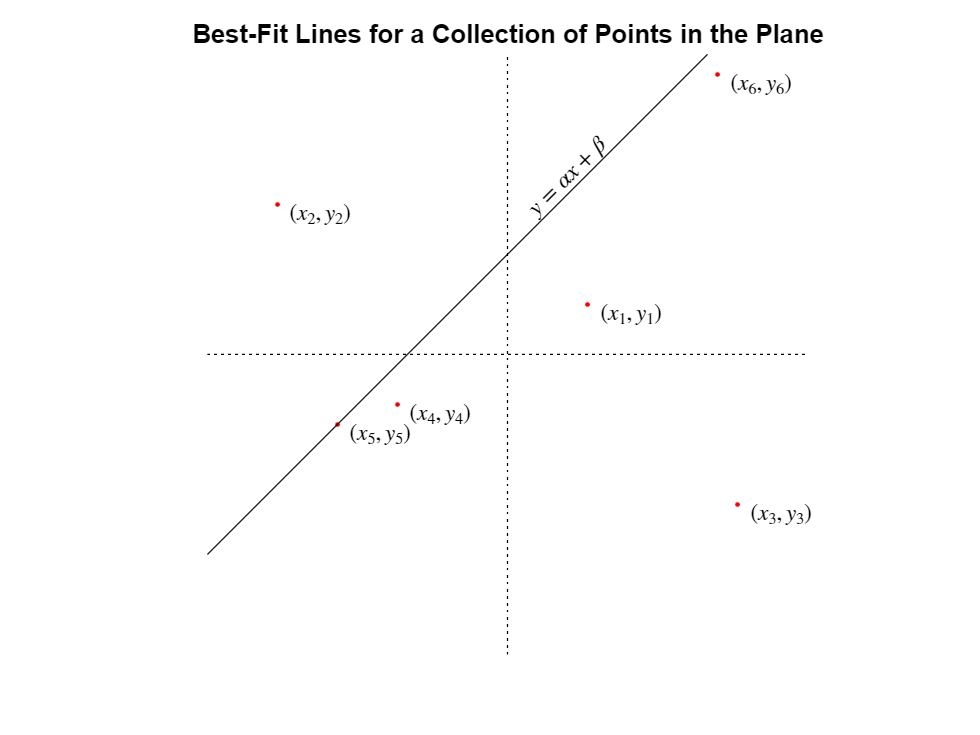

figII8d()

The linear system for the model coefficients are

$\left[\matrix{x_1 & 1\cr x_2 & 1 \cr \vdots & \vdots \cr x_N & 1}\right]\left[\matrix{\alpha \cr\beta}\right]=\left[\matrix{y_1\cr y_2\cr \vdots\cr y_N}\right]$.

The normal equations are


$$\left[\matrix{x_1 & x_2 & \cdots & x_n\cr
1 & 1 & \cdots & 1}\right]
\left[\matrix{x_1 & 1\cr x_2 & 1 \cr \vdots & \vdots \cr x_N & 1}\right]\left[\matrix{\alpha \cr\beta}\right]=\left[\matrix{x_1 & x_2 & \cdots & x_n\cr
1 & 1 & \cdots & 1}\right]\left[\matrix{y_1\cr y_2\cr \vdots\cr y_N}\right]\quad\Rightarrow\quad
$$


               
$$\left[\matrix{\sum_{\ell=1}^N x_\ell^2 & \sum_{\ell=1}^N x_\ell \cr
\sum_{\ell=1}^N x_\ell & N}\right] \left[\matrix{\alpha\cr\beta}\right]=\left[\matrix{\sum_{\ell=1}^N x_\ell y_\ell \cr \sum_{\ell=1}^N y_\ell}\right]$$


Hence,

     (II.8.13)        $\alpha=\frac{N\,C~-~X\,Y}{N\,S~-~X^2}$    and    $\beta=\frac{Y\,S~-~X\,C}{N\,S~-~X^2}$

where 

     (II.8.14)        $S=\sum_{\ell=1}^N x_\ell^2,\qquad
X=\sum_{\ell=1}^N x_\ell, \qquad
Y=\sum_{\ell=1}^N y_\ell, \quad\text{and}\quad
C=\sum_{\ell=1}^N x_\ell y_\ell.$

**Eigenvalues and eigenvectors of projection matrices.    **For any square matrix $A$ with an eigenvector ${\bf v}$ in a nonzero eigenvalue $\lambda$,

            $A{\bf v}=\lambda{\bf v}\qquad\Rightarrow\qquad
{\bf v}=\frac1\lambda A{\bf v}\qquad\Rightarrow\qquad
{\bf v}\in\text{col}(A)$.

On the other hand, if the eigenvalue $\lambda$ of an eigenvector ${\bf v}$ is zero, then

            $A{\bf v}=0{\bf v}={\bf 0}\qquad\Rightarrow\qquad
{\bf v}\in \text{nul}(A)$.

Thus, every eigenvector is either in the column space of the matrix or the null space of the matrix.   For a projection matrix $P$ (which has the property $P^2=P$) with an eigenvector ${\bf v}$ having eigenvalue $\lambda$, not only is $P{\bf v}=\lambda{\bf v}$ but also $P{\bf v}=P^2{\bf v}=P(\lambda{\bf v})=\lambda (P{\bf v})=\lambda(\lambda{\bf v})=\lambda^2{\bf v}$.   Hence, $\lambda=\lambda^2$ which implies either $\lambda=0$ or $\lambda=1$.   That is, the only possible eigenvalues of a projection matrix are 0 and 1.   From the observation above, if the eigenvalue is 1 then the eigenvector is in the column space of $P$, and if the eigenvalue is 0 then the eigenvector is in the null space of $P$.    Diagonalization of a projection matrix $P$ may be accomplished by combining a basis for $\text{col}(P)$ (all elements of which are eigenvectors with eigenvalue 1) with a basis for $\text{nul}(P)$ (all elements of which are eigenvector with eigenvalue 0).

**Example  II.8.1.   **Let $P=\left[\matrix{0 & 2 & -1 \cr -1 & 3 & -1 \cr -2 & 4 & -1}\right]$.

P=[0 2 -1; -1 3 -1; -2 4 -1];
P^2           % checking P is a projection

ans =        0              2             -1       
      -1              3             -1       
      -2              4             -1       


rref(P)

ans =        1              0             -1/2     
       0              1             -1/2     
       0              0              0       


N=[1/2; 1/2; 1];       % basis for the null space
P*N                    % check column of N is in null space

ans =        0       
       0       
       0       


C=[0 2; -1 3; -2 4];   % pivot columns of P (basis of column space)
S=[C N]                % combining the bases (eigenvectors)

S =        0              2              1/2     
      -1              3              1/2     
      -2              4              1       


D=diag([1 1 0])        % eigenvalues place in the diagaonal matrix

D =        1              0              0       
       0              1              0       
       0              0              0       


S*D*inv(S)             % checking the diagonalization

ans =        0              2             -1       
      -1              3             -1       
      -2              4             -1       


**Appendix II.8A:  Minimizing Euclidean distance implies orthogonal projection.  **Let ${\bf p}$ be the point in the subspace $V$closest to a given point ${\bf x}$.   Then $D({\bf u})=||{\bf x}-{\bf u}||^2$ is minimized for $u\in V$ by ${\bf p}$.   That is,

        $D({\bf p})\le D({\bf p}+s{\bf u})\quad\text{for}\quad u\in V\quad\text{and}\quad s\in{\mathbb R}$.  

Hence, if $f(s)=D({\bf p}+s{\bf u})$, then $f(s)$ is minimized for $s=0$.   Since

        $f(s)=||{\bf x}-{\bf p}-s{\bf u}||^2=||{\bf x}-{\bf p}||^2-2s{\bf u}\cdot({\bf x}-{\bf p})+s^2||{\bf u}||^2$,

        $f'(s)=-2{\bf u}\cdot({\bf x}-{\bf p})~+~2s||{\bf u}||^2$.

Hence,

        
$$0=f'(0)=-2{\bf u}\cdot({\bf x}-{\bf p})\quad\Rightarrow\quad
{\bf u}\cdot({\bf x}-{\bf p})\quad\text{for}\quad {\bf u}\in V.$$


**Appendix II.8B:   Gram matrix of matrix with independent columns is invertible.**  We assume the Gram matrix is not invertible and derive a contradiction.   Suppose the $m\times k$ matrix $A$ has linearly independent columns, but the Gram matrix $A^TA$ is singular.  Since $A^TA$ has a free variable, there is a nontrivial solution of the homogeneous system $A^TA{\bf x}={\bf 0}$.   Multiplying on the left by ${\bf x}^T$ gives ${\bf x}^TA^TA{\bf x}=0$.  Hence,

        $0={\bf x}^TA^TA{\bf x}=(A{\bf x})^T(A{\bf x})=||A{\bf x}||^2 \qquad\Rightarrow\qquad
{\bf 0}=A{\bf x}=x_1{\bf a}_1+\cdots+x_k{\bf a}_k$.

This nontrivial linear combination of the columns of$A$ contradicts the columns of$A$being linearly independent.

**Problem II.8.1:  **Show that a vector $\mathbf{d}$ is orthogonal to a subspace $S$ if and only if it is orthogonal to each vector in a basis for $S$.

**Problem II.8.2:  **Derive (II.8.3b) from (II.8.3a).

**Problem II.8.3:  **Explain how equation (II.8.7) implies every vector in $V$ (except one) is an eigenvector of P.   What is the eigenvalue?   

**Problem II.8.4:  **If $A$ has linearly independent columns and $P=A(A^TA)^{-1}A^T$what is $PA$?

**Problem II.8.5:**  Find the orthogonal projection matrix into each of the following subspaces.


$$\quad\text{(a)}\quad \text{col}\left(\left[\matrix{1\cr2}\right]\right)\qquad
\quad\text{(b)}\quad \text{col}\left(\left[\matrix{1&2\cr2&1\cr0&0}\right]\right)\qquad
\quad\text{(c)}\quad \text{col}\left(\left[\matrix{1&1\cr2&1\cr1&1}\right]\right)\qquad$$


**Problem II.8.6:  **Show that if $P$ is an orthogonal projection and $Q=I-P$ then (a) $P+Q=I$ and (b) $PQ=QP=O$ where $O$ is a zero matrix.

**Problem II.8.7:**  Find the orthogonal projection matrix into the orthogonal complements of the subspaces in Problem II.8.5.

**Problem II.8.8:**  Find the least-squares solutions of each of the following linear systems.


$$\quad\text{(a)}\quad\left[\matrix{1&1&0\cr1&2&1\cr0&1&1}\right]{\bf x}=\left[\matrix{1\cr1\cr1}\right]\qquad
\quad\text{(b)}\quad\left[\matrix{1&0&1\cr0&1&0\cr1&0&1}\right]{\bf x}=\left[\matrix{1\cr2\cr3}\right]\qquad
\quad\text{(c)}\quad\left[\matrix{0&1&1\cr1&0&1\cr1&1&0}\right]{\bf x}=\left[\matrix{2\cr2\cr2}\right]\qquad
$$


**Problem II.8.9:**  Find the best-fit line for the data:   $(x_1,y_1)=(1,2),~(x_2,y_2)=(1,1),~(x_3,y_3)=(1,0),~(x_4,y_4)=(0,0),~(x_5,y_5)=(-1,-1)$.

**Problem II.8.10:**  Find the coefficients for which the data

$(x_1,y_1)=(1,2),~(x_2,y_2)=(1,1),~(x_3,y_3)=(1,0),~(x_4,y_4)=(0,0),~(x_5,y_5)=(-1,-1)$.

that best fits the model $y~=~\alpha ~+~ \beta x^2$.

**Problem II.8.11:   **Show that $Q=\left[\matrix{1 & -2 & 1 \cr 1 & -2 & 1 \cr 2 & -4 & 2}\right]$ is a projection matrix and diagonalize it.

**Problem II.8.12:   **Take the determinant of the matrix equation $P^2=P$, and show $|P|=1$or $|P|=0$.

function figII8a()
clf
axis([-3 3 -3 3])
axis square
axis off
hold on
title('Orthogonal Projection of a Vector into a Subspace')
subtitle('${\bf p}$ is the point in $V$ closest to ${\bf x}$','Interpreter','latex')
plot([0 0],[-3 3],':k')    % y-axis
plot([-3 3],[0 0],':k')    % x-axis
plot([-3 3],[-1 1],'b')    % subspace V
plot(4/3,8/3,'.r')         % point x
text(4/3+0.15,8/3,'${\bf x}$','Interpreter','latex')
plot(2,2/3,'.r')           % projection p
text(2+0.05,2/3-0.1,'${\bf p}$','Interpreter','latex')
plot([4/3 2],[8/3 2/3],':k')
text(0.05,-0.15,'${\bf 0}$','Interpreter','latex')
text(2.5,2/3+1/6+0.2,'$V$','Interpreter','latex')
end

function figII8b()
axis([-3 3 -3 3])
axis square
axis off
hold on
title('Decomposition into Orthogonal Components')
subtitle('${\bf x}={\bf p}+{\bf q}\quad$with$\quad{\bf p}\cdot{\bf q}=0$','Interpreter','latex')
plot([0 0],[-3 3],':k')    % y-axis
plot([-3 3],[0 0],':k')    % x-axis
plot([-3 3],[-1 1],'b')    % subspace col(A)
plot(4/3,8/3,'.r')         % point x
text(4/3+0.15,8/3,'${\bf x}$','Interpreter','latex')
plot(2,2/3,'.r')           % projection p
text(2+0.05,2/3-0.1,'${\bf p}=P{\bf x}$','Interpreter','latex')
plot([4/3 2],[8/3 2/3],':k')
text(0.05,-0.15,'${\bf 0}$','Interpreter','latex')
text(2.5,2/3+1/6+0.2,'$V$','Interpreter','latex')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
plot([1 -1],[-3 3],'b')    % subspace V perp
plot(-2/3,2,'.r')           % projection q
text(-2/3-0.9,2-0.02,'${\bf q}=Q{\bf x}$','Interpreter','latex')
plot([4/3 -2/3],[8/3 2],':k')
text(-0.8,2.75,'$V^\perp$','Interpreter','latex')
end

function figII8c()
clf
axis([-3 3 -3 3])
axis square
axis off
hold on
plot([0 0],[-3 3],':k')    % y-axis
plot([-3 3],[0 0],':k')    % x-axis
plot([-3 3],[-1 1],'b')    % subspace V
plot(5/3,5/3,'.r')         % point b
text(5/3+0.15,5/3,'${\bf b}$','Interpreter','latex')
plot(2,2/3,'.r')           % projection ^b
text(2+0.1,2/3-0.1,'$\hat{\bf b}=A{\bf x}$','Interpreter','latex')
plot([5/3 2],[5/3 2/3],':k')
text(0.05,-0.15,'${\bf 0}$','Interpreter','latex')
text(2.5,2/3+1/6+0.2,'$V$','Interpreter','latex')
title('Least-squares solutions')
end

function figII8d()
clf
axis([-3 3 -3 3])
axis square
axis off
hold on
title('Best-Fit Lines for a Collection of Points in the Plane')
plot([0 0],[-3 3],':k')    % y-axis
plot([-3 3],[0 0],':k')    % x-axis
x=0.8;
y=0.5;
plot(x,y,'.r')
text(x+0.1,y-0.1,'$(x_1,y_1)$','Interpreter','latex')
x=-2.3;
y=1.5;
plot(x,y,'.r')
text(x+0.1,y-0.1,'$(x_2,y_2)$','Interpreter','latex')
x=2.3;
y=-1.5;
plot(x,y,'.r')
text(x+0.1,y-0.1,'$(x_3,y_3)$','Interpreter','latex')
x=-1.1;
y=-0.5;
plot(x,y,'.r')
text(x+0.1,y-0.1,'$(x_4,y_4)$','Interpreter','latex')
x=-1.7;
y=-0.7;
plot(x,y,'.r')
text(x+0.1,y-0.1,'$(x_5,y_5)$','Interpreter','latex')
x=2.1;
y=2.8;
plot(x,y,'.r')
text(x+0.1,y-0.1,'$(x_6,y_6)$','Interpreter','latex')
plot([-3 2],[-2 3],'k')
text(0.2,1.4,'$y=\alpha x + \beta$','Interpreter','latex','rotation',45)
end
